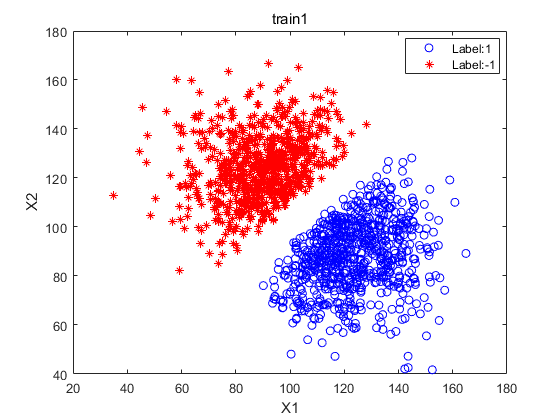

train_intNum = load("data5\data5\training_1.txt");
train_y = train_intNum(:, 3);
train_x = train_intNum(:, 1 : 2);
% 绘制散点图
figure;
gscatter(train_x(:,1), train_x(:,2), train_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('train1');

% 设置图例和形状
legend('Label:1', 'Label:-1');

% 设置惩罚参数
C = 100;
% alpha 为我们求解器返回的结果
[m,n] = size(train_x);
f = ones(m,1);
f = -f;
Aeq = train_y';
beq = 0;
lb = zeros(m, 1);
ub = C * ones(m, 1);

% 计算H
H = zeros(m);
for i  = 1 : m
   for j = 1 : m
      H(i, j) = train_y(i) * train_y(j) *(train_x(i, 1) * train_x(j, 1) + train_x(i, 2) * train_x(j , 2));
   end
end

alpha = quadprog(H, f, [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% train_x(1)

% 计算w
w = [0, 0];
for i = 1 : m
    t = alpha(i) * train_y(i) * train_x(i, :);
    w = w + t;
end

% 计算b
b = 0;
for s = 1 : m
    for i = 1 : m
        t = alpha(i) * train_y(i) * dot(train_x(i,:), train_x(s,:));
    end
    t2 = 1/train_y(s) - t;
    b = b + t2;
end
b = b / m;

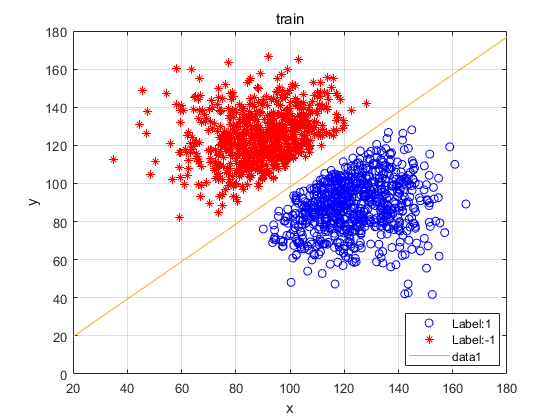

% 绘结果
figure;
gscatter(train_x(:,1), train_x(:,2), train_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('train1');

% 设置图例和形状
legend('Label:1', 'Label:-1');
hold on
x = linspace(190, 10);  % 在指定范围内生成 x 值
% 计算直线的斜率和截距
m = -w(1) / w(2);       % 斜率
c = -b / w(2);          % 截距
% 计算直线的 y 值
y = m * x + c;

% 绘制直线
plot(x, y);
xlabel('x');
ylabel('y');
title('train');
grid on;

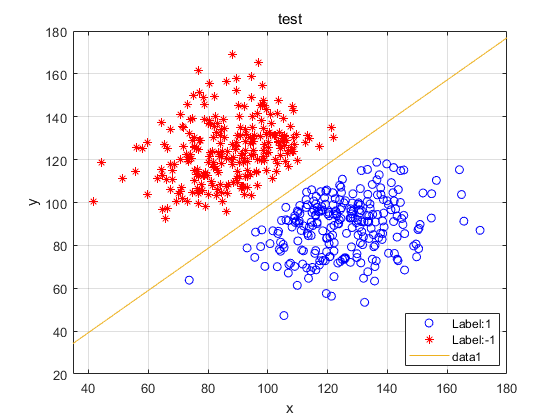

% 测试集
test_intNum = load("data5\data5\test_1.txt");
test_y = test_intNum(:, 3);
test_x = test_intNum(:, 1 : 2);
% 绘制散点图
figure;
gscatter(test_x(:,1), test_x(:,2), test_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('test1');

% 设置图例和形状
legend('Label:1', 'Label:-1');

% 绘制SVM直线
hold on
x = linspace(190, 10);  % 在指定范围内生成 x 值
% 计算直线的斜率和截距
m = -w(1) / w(2);       % 斜率
c = -b / w(2);          % 截距
% 计算直线的 y 值
y = m * x + c;

% 绘制直线
plot(x, y);
xlabel('x');
ylabel('y');
title('test');
grid on;

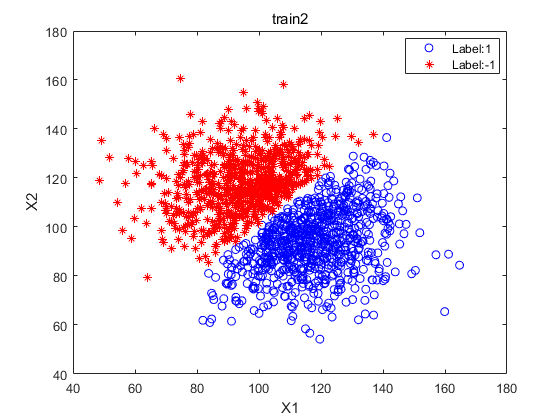

% 第二组数据

train_intNum = load("data5\data5\training_2.txt");
train_y = train_intNum(:, 3);
train_x = train_intNum(:, 1 : 2);
% 绘制散点图
figure;
gscatter(train_x(:,1), train_x(:,2), train_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('train2');

% 设置图例和形状
legend('Label:1', 'Label:-1');


% 设置惩罚参数
C = 0.0001;
% alpha 为我们求解器返回的结果
[m,n] = size(train_x);
f = ones(m,1);
f = -f;
Aeq = train_y';
beq = 0;
lb = zeros(m, 1);
ub = C * ones(m, 1);

% 计算H
H = zeros(m);
for i  = 1 : m
   for j = 1 : m
      H(i, j) = train_y(i) * train_y(j) *(train_x(i, 1) * train_x(j, 1) + train_x(i, 2) * train_x(j , 2));
   end
end

alpha = quadprog(H, f, [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% train_x(1)

% 计算w
w = [0, 0];
for i = 1 : m
    t = alpha(i) * train_y(i) * train_x(i, :);
    w = w + t;
end

% 计算b
b = 0;
for s = 1 : m
    for i = 1 : m
        t = alpha(i) * train_y(i) * dot(train_x(i,:), train_x(s,:));
    end
    t2 = 1/train_y(s) - t;
    b = b + t2;
end
b = b / m;

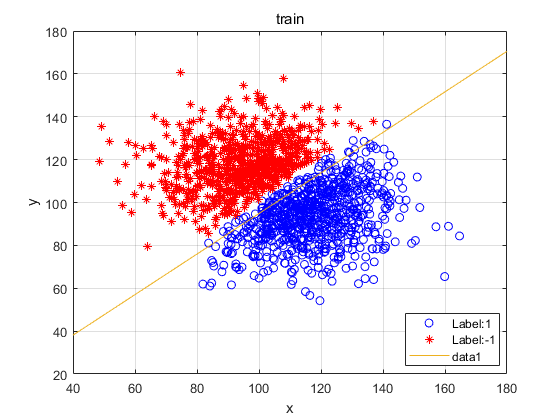

% 绘结果
figure;
gscatter(train_x(:,1), train_x(:,2), train_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('train1');

% 设置图例和形状
legend('Label:1', 'Label:-1');
hold on
x = linspace(190, 10);  % 在指定范围内生成 x 值
% 计算直线的斜率和截距
m = -w(1) / w(2);       % 斜率
c = -b / w(2);          % 截距
% 计算直线的 y 值
y = m * x + c;

% 绘制直线
plot(x, y);
xlabel('x');
ylabel('y');
title('train');
grid on;

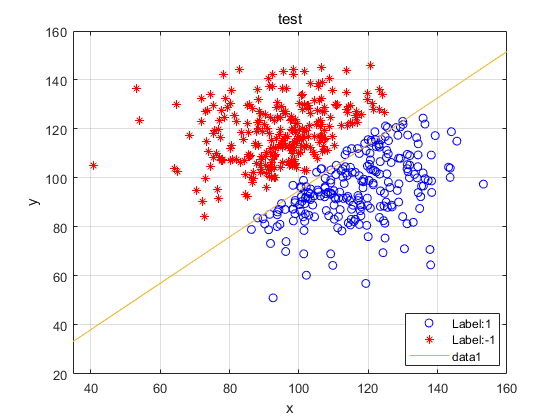

% 测试集
test_intNum = load("data5\data5\test_2.txt");
test_y = test_intNum(:, 3);
test_x = test_intNum(:, 1 : 2);
% 绘制散点图
figure;
gscatter(test_x(:,1), test_x(:,2), test_y, 'br', 'o*'); % 根据标签数据绘制散点图
xlabel('X1');
ylabel('X2');
title('test1');

% 设置图例和形状
legend('Label:1', 'Label:-1');

% 绘制SVM直线
hold on
x = linspace(190, 10);  % 在指定范围内生成 x 值
% 计算直线的斜率和截距
m = -w(1) / w(2);       % 斜率
c = -b / w(2);          % 截距
% 计算直线的 y 值
y = m * x + c;

% 绘制直线
plot(x, y);
xlabel('x');
ylabel('y');
title('test');
grid on;